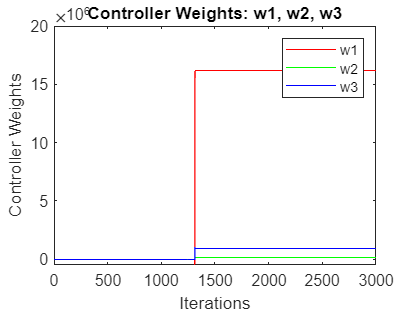

clear;clc;

N = 3000; 

% Given values 

K = 1.1;
n1 = 15;
n2 = 1;
n3 = 10;

alpha_p = 1;
alpha_i = 0.5;
alpha_d = 0.5;

zeta_p = 0.1;
zeta_i = 0.4;
zeta_d = 0.3;

u = zeros(N, 1);
y = zeros(N, 1);

w1 = ones(N, 1) * 0.005;
w2 = ones(N, 1) * 0.005;
w3 = ones(N, 1) * 0.005;

etr = zeros(N, 1);
Ts = 0.01;


P = zeros(N, 1);
I = zeros(N, 1);
D = zeros(N, 1);

xp = zeros(N, 1);
xi = zeros(N, 1);
xd = zeros(N, 1);

t_vec=0:Ts:30;

r = @(t) 1 + exp(-2*pi*t/100) * sin(t);

f = @(x, alfa, zeta) double(abs(x)>zeta)*sign(x)*abs(x)^alfa + double(abs(x)<=zeta)*zeta^(alfa-1);

n=2;

while n<N
    %Step 1: Calculate tracking error
    etr(n) = r((n-1) * Ts) - y(n);

    %Step 2: Calculate inputs of the PID Controller
    P(n) = etr(n);
    I(n) = I(n-1) + etr(n);
    D(n) = etr(n) - etr(n-1);

    %Step 3: Calculate outputs of f(.) nonlinear function
    xp(n) = f(etr(n), alpha_p, zeta_p);
    xi(n) = f(I(n), alpha_i, zeta_i);
    xd(n) = f(D(n), alpha_d, zeta_d);
    
    % Step 4: Calculate control signal 
    u(n) = K * (w1(n) * xp(n) + w2(n) * xi(n) + w3(n) * xd(n)) / (w1(n) + w2(n) + w3(n));

    % Step 5: Apply control signal to the plant and obtain output of the system
    y(n + 1) = 0.7708 * y(n) + 0.4484 * u(n);

    % Step 6: Update controller parameters 
    w1(n + 1) = w1(n) + n1 * etr(n) * u(n) * xp(n) ;
    w2(n + 1) = w2(n) + n2 * etr(n) * u(n) * xi(n) ;
    w3(n + 1) = w3(n) + n3 * etr(n) * u(n) * xd(n) ;
    
    % Step 7: n <-- n+1 and go to Step 1.
    n = n+1; 
end

figure(1)
plot(1:N, w1, 'r', 1:N, w2, 'g', 1:N, w3, 'b');
legend('w1', 'w2', 'w3');
xlabel('Iterations');
ylabel('Controller Weights');
title('Controller Weights: w1, w2, w3');

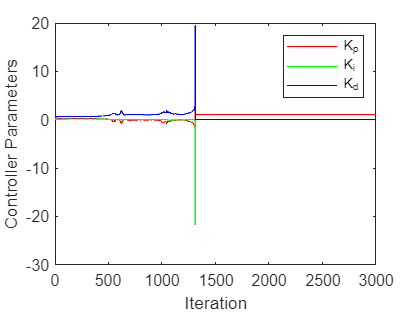


% Calculate K_p, K_i, K_d

K_p = K * w1 ./ (w1 + w2 + w3 );
K_i = K * w2 ./ (w1 + w2 + w3);
K_d = K * w3 ./ (w1 + w2 + w3 );

% Plot K_p, K_i, K_d

figure(2)
plot(1:N, K_p, 'r', 1:N, K_i, 'g', 1:N, K_d, 'b');
legend('K_p', 'K_i', 'K_d');
xlabel('Iteration');
ylabel('Controller Parameters');

figure(3)
plot(1:length(y),y);
legend("r(t)","Sytem Response");

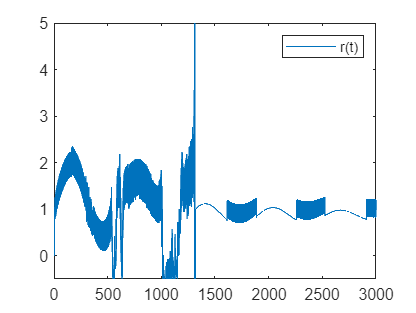

ylim([-0.5 5]);